# 遗传算法求解TSP问题

clc,clear,close all


## 基本参数

global NumCity
global PopSize


NumCity = 10;
PopSize = 1000;
Generation = 20;

global Pc
global Pm
global ac

Pc = 0.7;
Pm = 0.1;
ac = 2;

## 城市位置


global Positions 

Positions = [0.249486901976136	2.76505725175451
    1.52498315706327	1.20835248318157
    -0.722070071461637	1.95645054562943
    0.740493593327397	-1.47400590657446
    0.840495806240472	0.784868876206472
    -1.58398080249531	-1.12863604770022
    0.401719115246806	1.29127724924451
    0.457653673653943	-0.613485893425892
    0.281403901483382	-0.362938544782647
    1.70594818637433	-0.212540089334875];

## 城市距离

global Distance

Distance = zeros(NumCity);
for i = 1:NumCity
    for j = i+1 : NumCity
        Distance(i,j) = sqrt((Positions(i,1)-Positions(j,1)).^2 +...
            (Positions(i,2)-Positions(j,2)).^2);
        Distance(j,i) = Distance(i,j);
    end
end


## 初始化种群

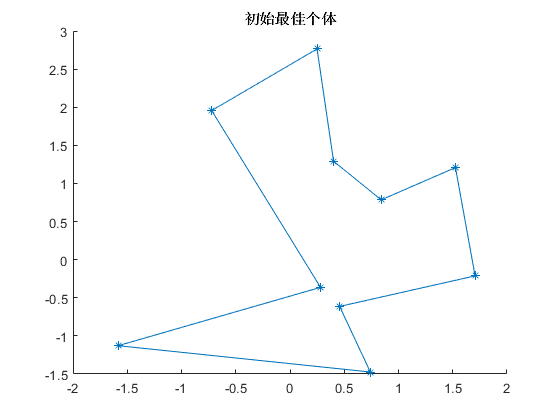

Pop = zeros(PopSize,NumCity);

for i = 1:PopSize
    Pop(i,:) = randperm(NumCity);
end

PopLength = zeros(PopSize,1);
for i = 1:PopSize
    PopLength(i) = TotalLength(Pop(i,:));
end

MaxPopLen = max(PopLength);
[MinPopLen,MinPopIdx] = min(PopLength);
Fitness = FindFit(PopLength,MaxPopLen,MinPopLen);

figure;
hold on
PlotMap(Pop(MinPopIdx,:))
title('初始最佳个体');
hold off

disp(MinPopLen)

   14.7635




BestIndivLen = MinPopLen;
BestIndividual = Pop(MinPopIdx,:);
BestGeneration = 0;

## 开始进化

for j = 1:Generation
    Pop = Select(Pop,Fitness);
    Pop = CrossOver(Pop);
    Pop = Mutate(Pop);
    
    for i = 1:PopSize
        PopLength(i) = TotalLength(Pop(i,:));
    end
    
    MaxPopLen = max(PopLength);
    [MinPopLen,MinPopIdx] = min(PopLength);
    Fitness = FindFit(PopLength,MaxPopLen,MinPopLen);
    
    if MinPopLen < BestIndivLen
        BestIndivLen = MinPopLen;
        BestIndividual = Pop(MinPopIdx,:);
        BestGeneration = j;
    end

end


## 结果

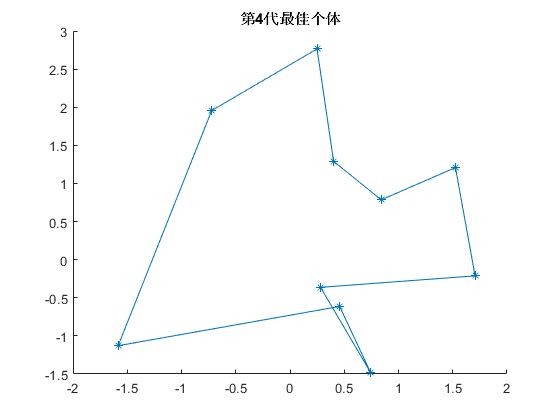

figure;
hold on
PlotMap(BestIndividual)
title(['第',num2str(BestGeneration),'代最佳个体']);
hold off

disp(BestIndivLen)

   14.5023



## 相关函数

function PlotMap(Individual)

global NumCity
global Positions

A = zeros(NumCity);

for i = 1:NumCity - 1
    A(Individual(i),Individual(i+1)) = 1;
    A(Individual(i+1),Individual(i)) = 1;
end
A(Individual(1),Individual(end)) = 1;
A(Individual(end),Individual(1)) = 1;

gplot(A,Positions,'-*')

end


## 个体距离

function IndividualLen = TotalLength(Individual)

global NumCity
global Distance

IndividualLen = Distance(Individual(NumCity),Individual(1));
for i = 1:NumCity - 1
    IndividualLen = IndividualLen + Distance(Individual(i),Individual(i+1));
end

end




## 适应度函数

function Fitness = FindFit(PopLen,MaxPopLen,MinPopLen)

global ac

Fitness = (1-(PopLen - MinPopLen)/(MaxPopLen - MinPopLen + 1e-4)).^ac;

end


## 选择复制

function NewPop = Select(Pop,Fitness)

global PopSize
Fitness = cumsum(Fitness/sum(Fitness));

NewPop = Pop;

SelectRate = sort(rand(PopSize,1));

FitIdx = 1;
NewIdx = 1;

while NewIdx <= PopSize
    if SelectRate(NewIdx) < Fitness(FitIdx)
        NewPop(NewIdx,:) = Pop(FitIdx,:);
        NewIdx = NewIdx + 1;
    else
        FitIdx = FitIdx + 1;
    end
end

end



## 交叉

### 交叉两个个体

function [IndividualA,IndividualB] = Cross(IndividualA,IndividualB)

global NumCity

%% 按正态分布随机抽取交叉长度
CrossLength = round(randn + (NumCity+1)/2);
if CrossLength < 1
    CrossLength = 1;
elseif CrossLength > NumCity
    CrossLength = NumCity;
end

%% 按均匀分布随机抽取交叉起始位点
CrossPoint = ceil(rand * (NumCity - CrossLength + 1));

%% 交叉基因段
CrossChromA = IndividualA(CrossPoint:CrossPoint + CrossLength - 1);
CrossChromB = IndividualB(CrossPoint:CrossPoint + CrossLength - 1);

%% 去除交叉基因
for i = 1:CrossLength
    IndividualA(IndividualA == CrossChromB(i)) = [];
    IndividualB(IndividualB == CrossChromA(i)) = [];
end

%% 合成新基因
IndividualA = [IndividualA(1:CrossPoint-1),CrossChromB,IndividualA(CrossPoint:end)];
IndividualB = [IndividualB(1:CrossPoint-1),CrossChromA,IndividualB(CrossPoint:end)];

end



### 选择交叉

function NewPop = CrossOver(Pop)

global Pc
global PopSize

NewPop = Pop;

for i = 1:2:PopSize-1
    if rand < Pc
        [NewPop(i,:),NewPop(i+1,:)] = Cross(NewPop(i,:),NewPop(i+1,:));
    end
end
end



## 变异

### 个体变异

function Individual = IndivMutate(Individual)

global NumCity

%% 按均匀分布随机抽取变异位点起始位点,并插入第三个位点之后
a = randperm(NumCity);
MutatePoint = sort(a(1:3));

Individual = [Individual(1:MutatePoint(1)-1),Individual(MutatePoint(2)+1:MutatePoint(3)),...
    Individual(MutatePoint(1):MutatePoint(2)),Individual(MutatePoint(3)+1:end)];

end

### 种群选择变异

function NewPop = Mutate(Pop)

global Pm
global PopSize

NewPop = Pop;
for i = 1:PopSize
    if rand < Pm
        IndivMutate(NewPop(i,:));
    end
end
end
